if(~exist(strcat('g2s.',mexext), 'file'))
   CompileG2S; 
end

source=imread('source.png');
set(0,'DefaultFigureWindowStyle','docked')

serverAddress='localhost';

## simple echo

data=g2s('-sa',serverAddress,'-a','echo','-ti',single(source))/255;

Send job
job Id is: 510392639
progres 100.000%


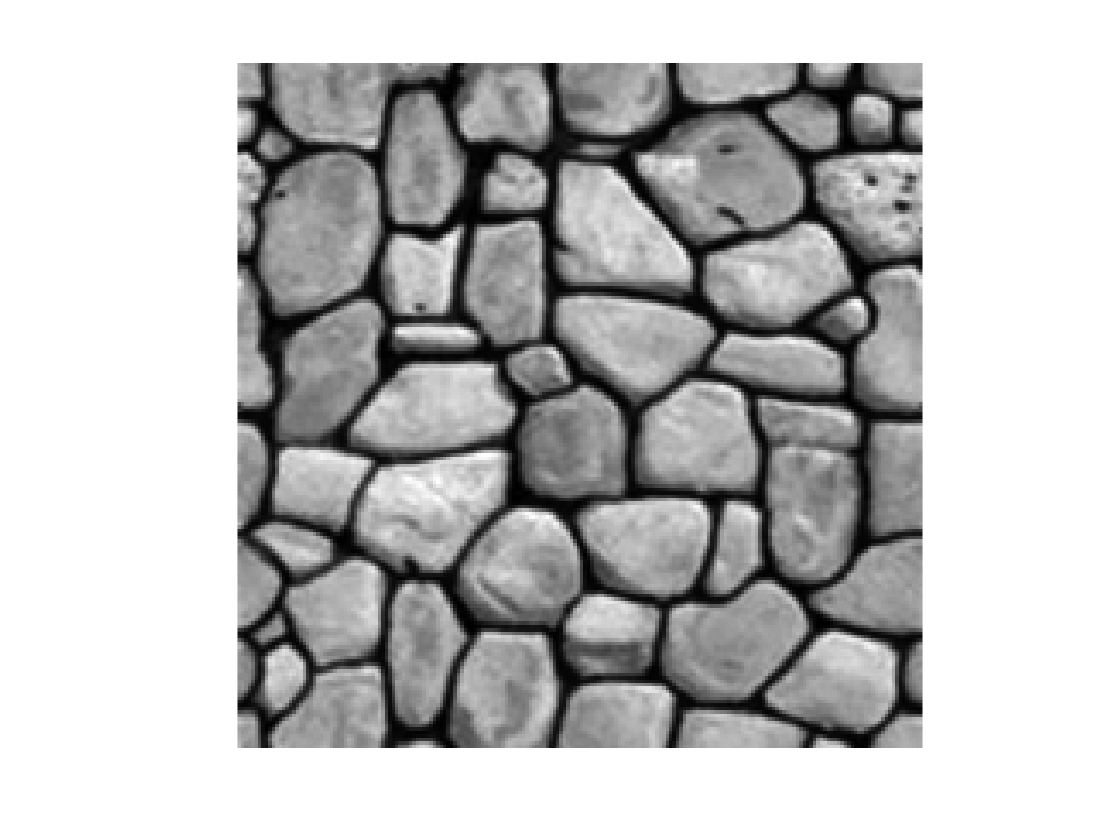

imshow(data);

## simple non conditional simulation with QS

data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100)/255);

Send job
job Id is: 3074157455
progres 1.000%
progres 2.000%
progres 5.000%
progres 9.000%
progres 13.000%
progres 16.000%
progres 20.000%
progres 24.000%
progres 28.000%
progres 32.000%
progres 37.000%
progres 41.000%
progres 45.000%
progres 50.000%
progres 54.000%
progres 58.000%
progres 62.000%
progres 66.000%
progres 70.000%
progres 74.000%
progres 80.000%
progres 90.000%
progres 94.000%
progres 98.000%
progres 99.000%
progres 100.000%


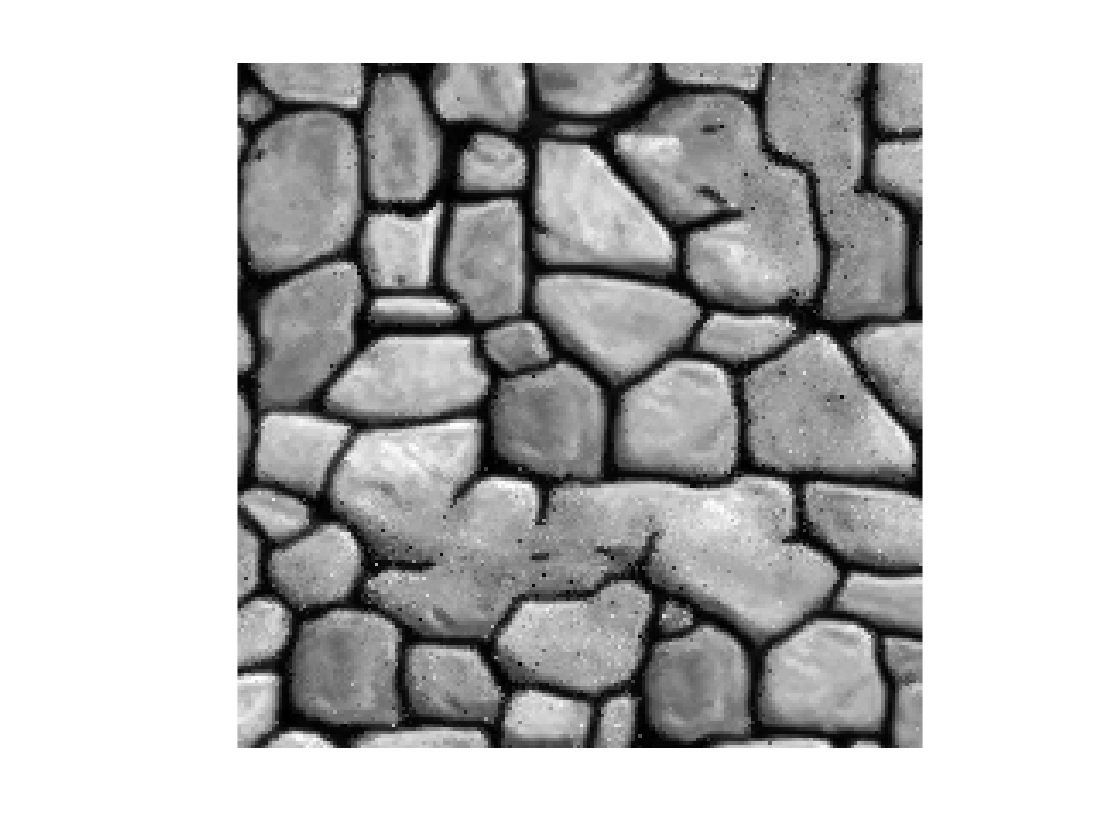

imshow(data)


%with GPU is integrated GPU avaible
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-W_GPU')/255);

Send job
job Id is: 526806243
progres 0.000%
progres 2.000%
progres 5.000%
progres 8.000%
progres 12.000%
progres 16.000%
progres 20.000%
progres 24.000%
progres 28.000%
progres 33.000%
progres 37.000%
progres 41.000%
progres 45.000%
progres 50.000%
progres 54.000%
progres 58.000%
progres 62.000%
progres 67.000%
progres 71.000%
progres 75.000%
progres 80.000%
progres 84.000%
progres 88.000%
progres 93.000%
progres 97.000%
progres 99.000%
progres 100.000%


imshow(data)

## simple conditional simulation with QS

pourcantage=0.25; %% 0.25%
dest=nan.*ones(200);
sizeDest=length(dest(:));

position=randperm(sizeDest,sizeDest*pourcantage/100);

dest(position)=source(position);

% simuulation of the source
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);

Send job
job Id is: 1869973688
progres 1.000%
progres 3.000%
progres 7.000%
progres 11.000%
progres 19.000%
progres 23.000%
progres 27.000%
progres 31.000%
progres 37.000%
progres 41.000%
progres 46.000%
progres 50.000%
progres 54.000%
progres 58.000%
progres 62.000%
progres 66.000%
progres 71.000%
progres 75.000%
progres 79.000%
progres 83.000%
progres 87.000%
progres 92.000%
progres 96.000%
progres 99.000%
progres 100.000%


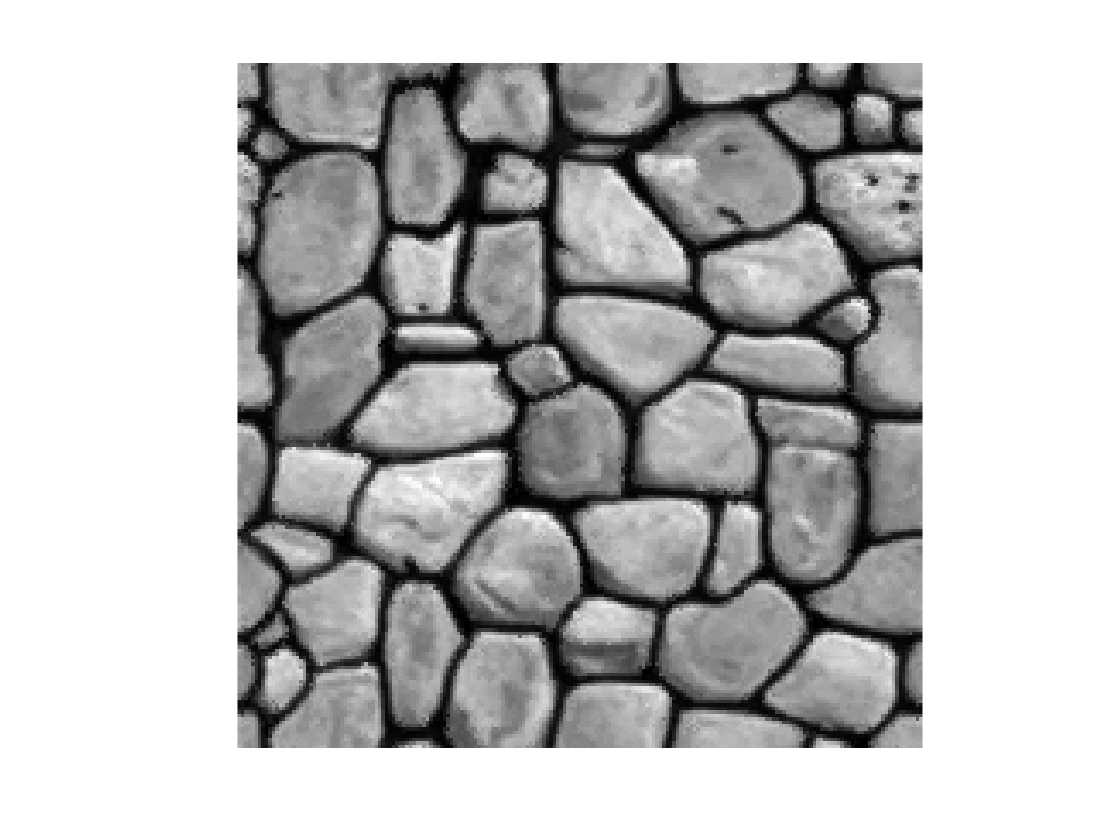

imshow(data)


% simulation with random value at random position
dest=dest*nan;
position2=randperm(sizeDest,sizeDest*pourcantage/100);
dest(position2)=source(position);

% simuulation of the source
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);

Send job
job Id is: 1939589332
progres 0.000%
progres 2.000%
progres 5.000%
progres 9.000%
progres 13.000%
progres 17.000%
progres 20.000%
progres 24.000%
progres 28.000%
progres 32.000%
progres 36.000%
progres 41.000%
progres 45.000%
progres 49.000%
progres 53.000%
progres 57.000%
progres 61.000%
progres 65.000%
progres 70.000%
progres 74.000%
progres 78.000%
progres 82.000%
progres 86.000%
progres 90.000%
progres 95.000%
progres 99.000%
progres 100.000%


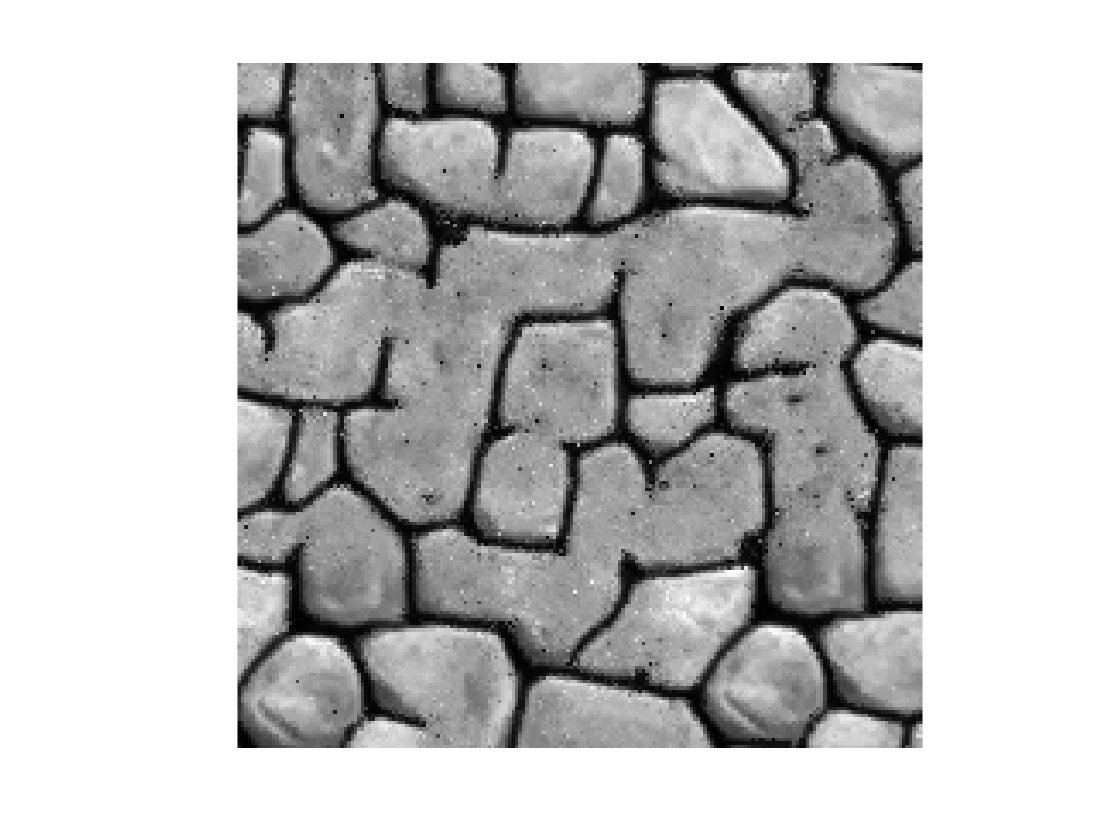

imshow(data)

## simple non conditional simulation with multi TI of differente size

%data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source(:,1:150)),single(rot90(source,1)),single(rot90(source(:,1:175),2)),single(rot90(source(:,1:150),3)),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),single(rot90(source,1)),single(rot90(source,2)),single(rot90(source,3)),'-di',single(dest),'-k',1.5,'-n',50,'-s',100)/255);

Send job
job Id is: 499129201
progres 0.000%
progres 1.000%
progres 2.000%
progres 3.000%
progres 4.000%
progres 5.000%
progres 7.000%
progres 8.000%
progres 9.000%
progres 10.000%
progres 11.000%
progres 12.000%
progres 13.000%
progres 14.000%
progres 15.000%
progres 16.000%
progres 17.000%
progres 19.000%
progres 20.000%
progres 21.000%
progres 22.000%
progres 23.000%
progres 24.000%
progres 25.000%
progres 26.000%
progres 28.000%
progres 29.000%
progres 30.000%
progres 31.000%
progres 32.000%
progres 33.000%
progres 34.000%
progres 36.000%
progres 37.000%
progres 38.000%
progres 39.000%
progres 40.000%
progres 41.000%
progres 42.000%
progres 43.000%
progres 45.000%
progres 46.000%
progres 47.000%
progres 48.000%
progres 49.000%
progres 50.000%
progres 51.000%
progres 53.000%
progres 54.000%
progres 55.000%
progres 56.000%
progres 57.000%
progres 58.000%
progres 59.000%
progres 60.000%
progres 62.000%
progres 63.000%
progres 64.000%
progres 65.000%
progres 66.000%
progres 67.000%
pro

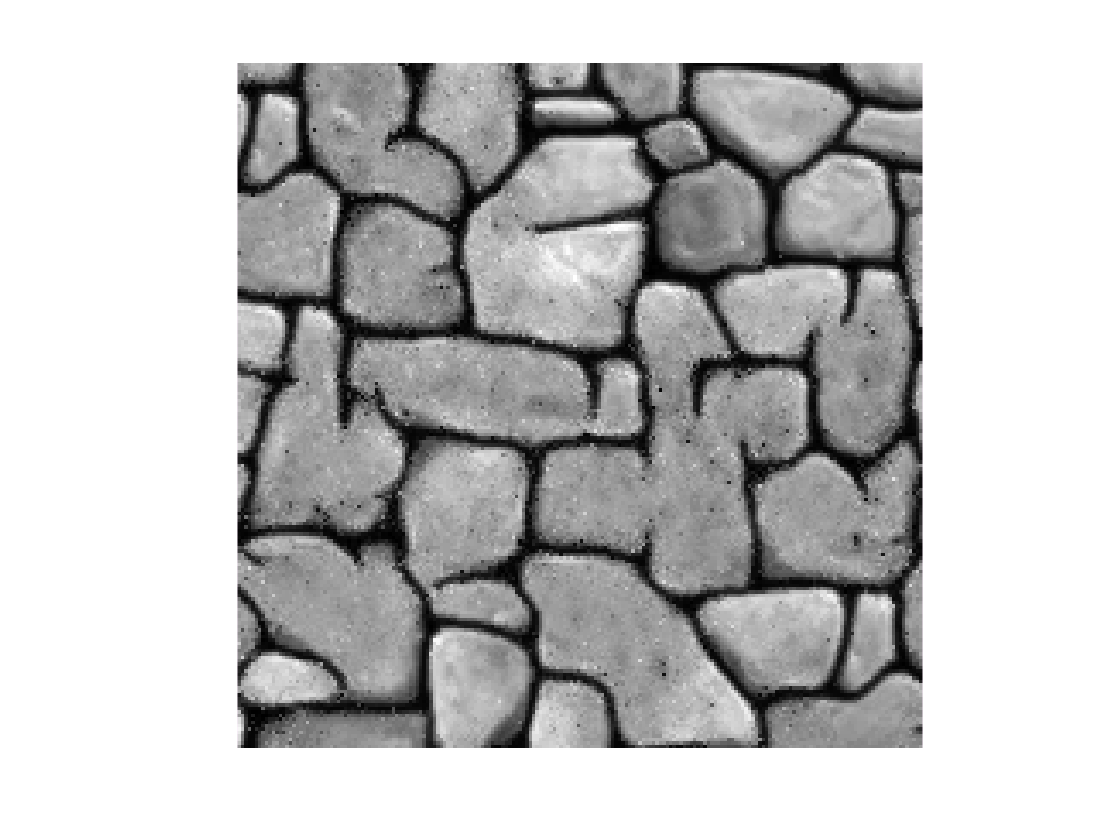

imshow(data)

## simulation with a fixed path

% row path
path=zeros(200);
path(:)=(1:200*200);
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-sp',path)/255);

Send job
job Id is: 4141744034
progres 2.000%
progres 5.000%
progres 9.000%
progres 12.000%
progres 17.000%
progres 21.000%
progres 26.000%
progres 30.000%
progres 35.000%
progres 39.000%
progres 43.000%
progres 48.000%
progres 52.000%
progres 57.000%
progres 61.000%
progres 66.000%
progres 70.000%
progres 75.000%
progres 79.000%
progres 83.000%
progres 87.000%
progres 92.000%
progres 96.000%
progres 99.000%
progres 100.000%


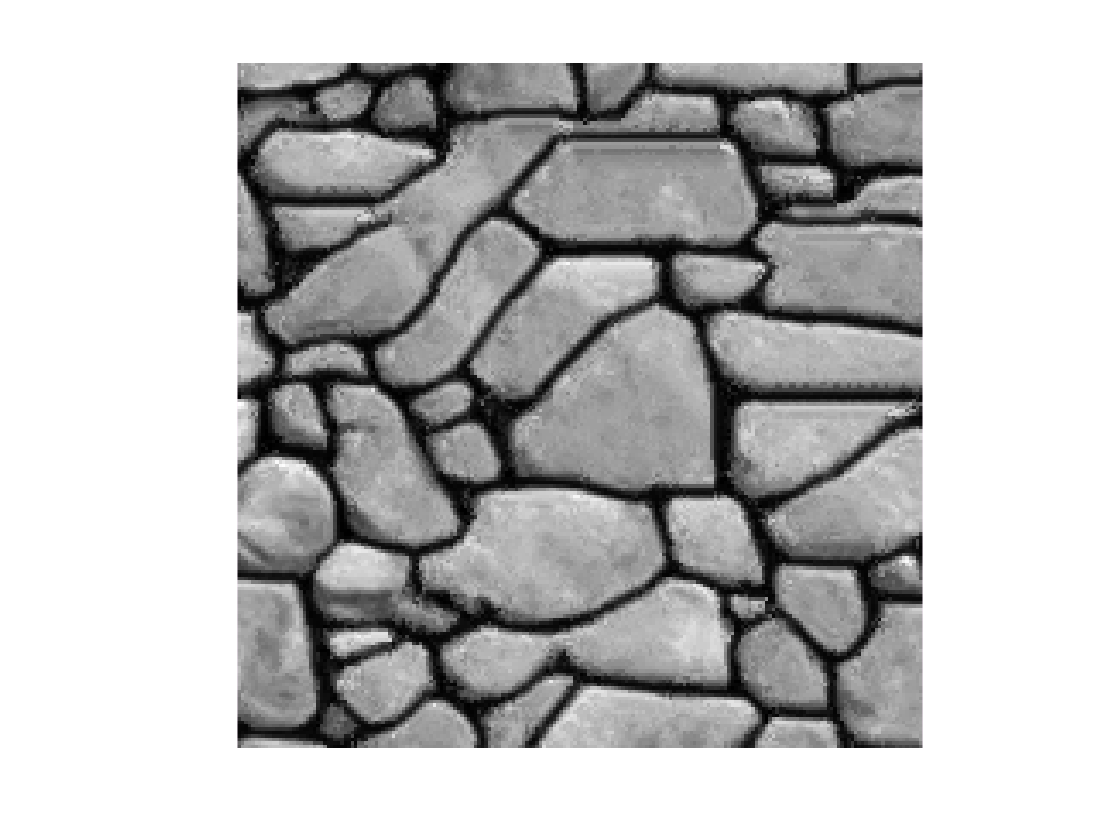

imshow(data)


% pathial random path
path=zeros(200);
path(:)=randperm(200*200);
path(randperm(200*200,200*200/2))=-inf;
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-sp',path)/255);

Send job
job Id is: 3430523489
progres 1.000%
progres 5.000%
progres 11.000%
progres 18.000%
progres 26.000%
progres 34.000%
progres 42.000%
progres 50.000%
progres 58.000%
progres 66.000%
progres 75.000%
progres 83.000%
progres 92.000%
progres 99.000%
progres 100.000%


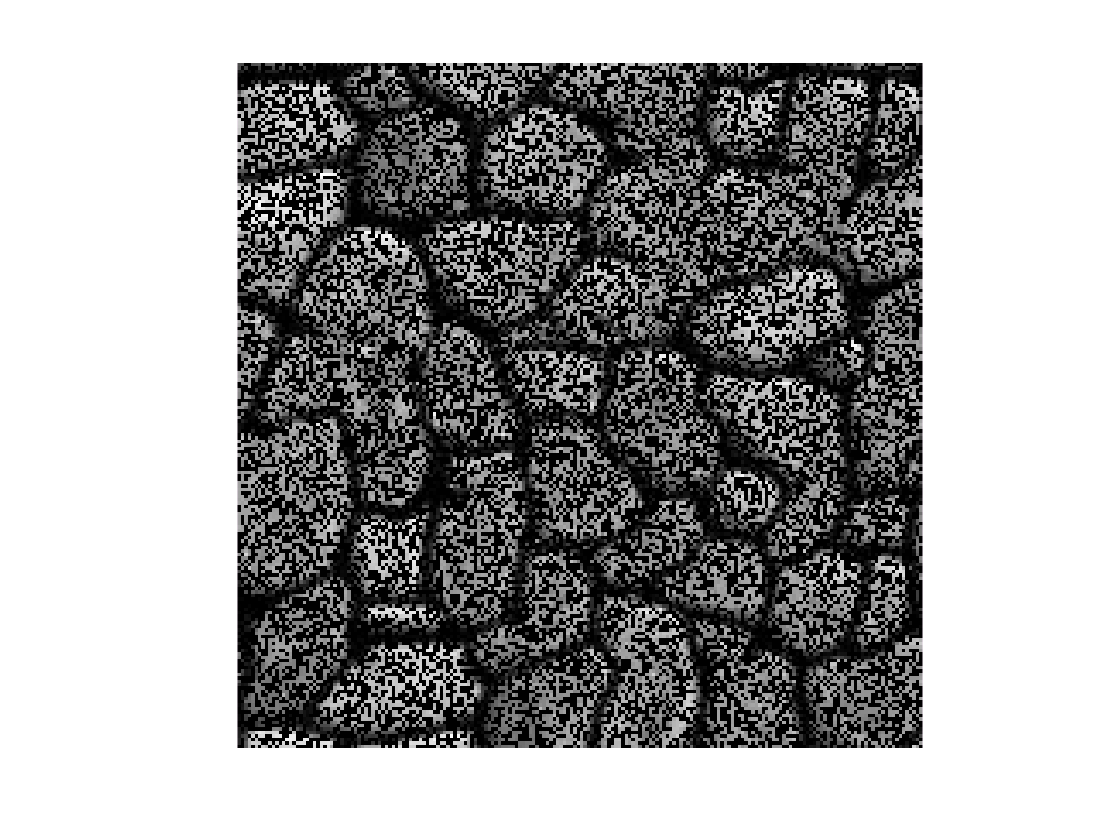

imshow(data)

## specifing a kernel

% ? kernel need to be define for each variable 

kernel=zeros(101,101);
kernel(51,51)=1;
kernel=exp(-0.1*bwdist(kernel));

data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source),'-di',single(nan.*ones(200)),'-k',1.5,'-n',50,'-s',100,'-ki',kernel)/255);

Send job
job Id is: 2267878946
progres 1.000%
progres 2.000%
progres 6.000%
progres 9.000%
progres 13.000%
progres 17.000%
progres 21.000%
progres 25.000%
progres 29.000%
progres 33.000%
progres 37.000%
progres 41.000%
progres 46.000%
progres 50.000%
progres 54.000%
progres 58.000%
progres 63.000%
progres 67.000%
progres 71.000%
progres 75.000%
progres 80.000%
progres 84.000%
progres 88.000%
progres 92.000%
progres 97.000%
progres 99.000%
progres 100.000%


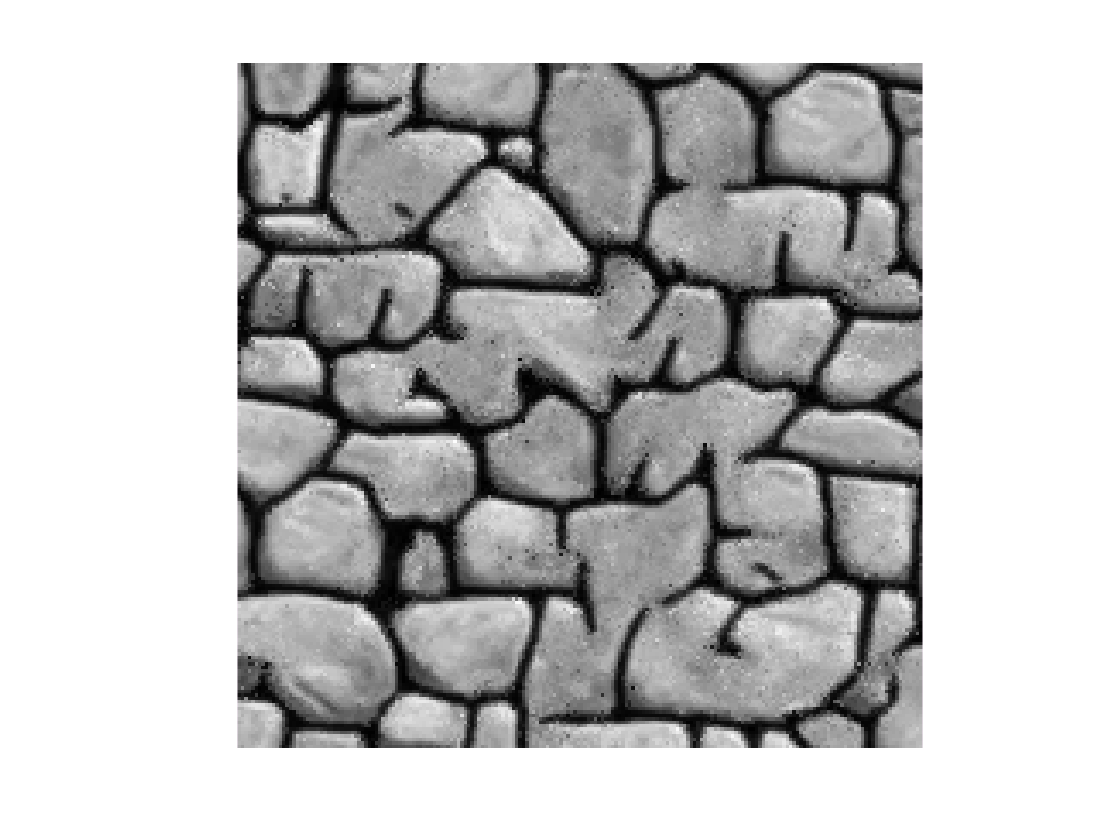

imshow(data)

## multi variete

source3=cat(3,source,source,source); %% need to fine better example
data=(g2s('-sa',serverAddress,'-a','qs','-ti',single(source3),'-di',single(nan.*ones(200,200,3)),'-k',2,'-n',50,'-s',100)/255);

Send job
job Id is: 3388296521
progres 0.000%
progres 1.000%
progres 2.000%
progres 4.000%
progres 5.000%
progres 7.000%
progres 9.000%
progres 10.000%
progres 12.000%
progres 14.000%
progres 15.000%
progres 17.000%
progres 19.000%
progres 21.000%
progres 23.000%
progres 24.000%
progres 26.000%
progres 28.000%
progres 30.000%
progres 31.000%
progres 33.000%
progres 35.000%
progres 37.000%
progres 39.000%
progres 41.000%
progres 42.000%
progres 44.000%
progres 46.000%
progres 48.000%
progres 50.000%
progres 52.000%
progres 54.000%
progres 55.000%
progres 57.000%
progres 65.000%
progres 67.000%
progres 69.000%
progres 70.000%
progres 72.000%
progres 74.000%
progres 76.000%
progres 78.000%
progres 80.000%
progres 82.000%
progres 83.000%
progres 85.000%
progres 87.000%
progres 89.000%
progres 91.000%
progres 93.000%
progres 94.000%
progres 96.000%
progres 98.000%
progres 99.000%
progres 100.000%


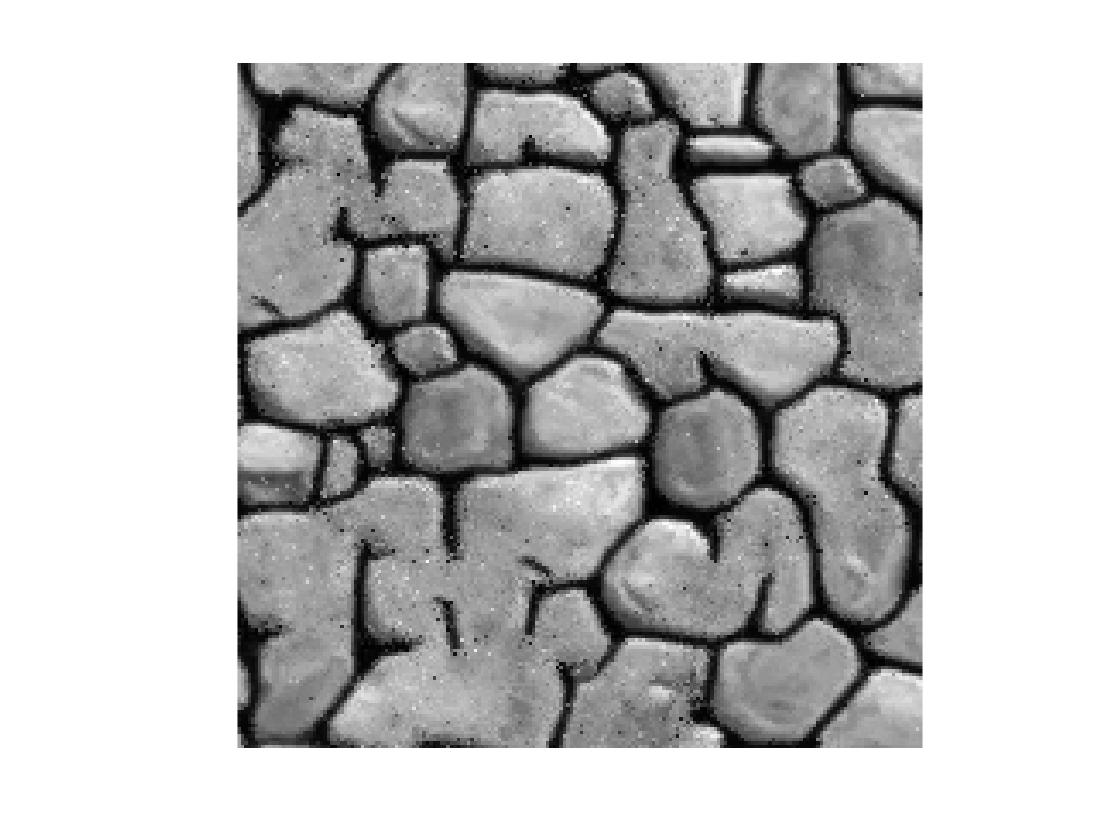

imshow(data)

## ds mode

data=(g2s('-sa',serverAddress,'-a','ds-l','-ti',single(source),'-di',single(nan.*ones(200)),'-th',10,'-f',0.3,'-n',50,'-s',100)/255);

Send job
job Id is: 3798094310
progres 0.000%
progres 1.000%
progres 3.000%
progres 4.000%
progres 9.000%
progres 11.000%
progres 13.000%
progres 15.000%
progres 17.000%
progres 19.000%
progres 21.000%
progres 23.000%
progres 25.000%
progres 27.000%
progres 29.000%
progres 31.000%
progres 33.000%
progres 36.000%
progres 38.000%
progres 40.000%
progres 42.000%
progres 44.000%
progres 46.000%
progres 48.000%
progres 50.000%
progres 52.000%
progres 54.000%
progres 57.000%
progres 59.000%
progres 61.000%
progres 63.000%
progres 65.000%
progres 67.000%
progres 70.000%
progres 72.000%
progres 74.000%
progres 76.000%
progres 78.000%
progres 81.000%
progres 83.000%
progres 85.000%
progres 87.000%
progres 90.000%
progres 92.000%
progres 94.000%
progres 97.000%
progres 99.000%
progres 100.000%


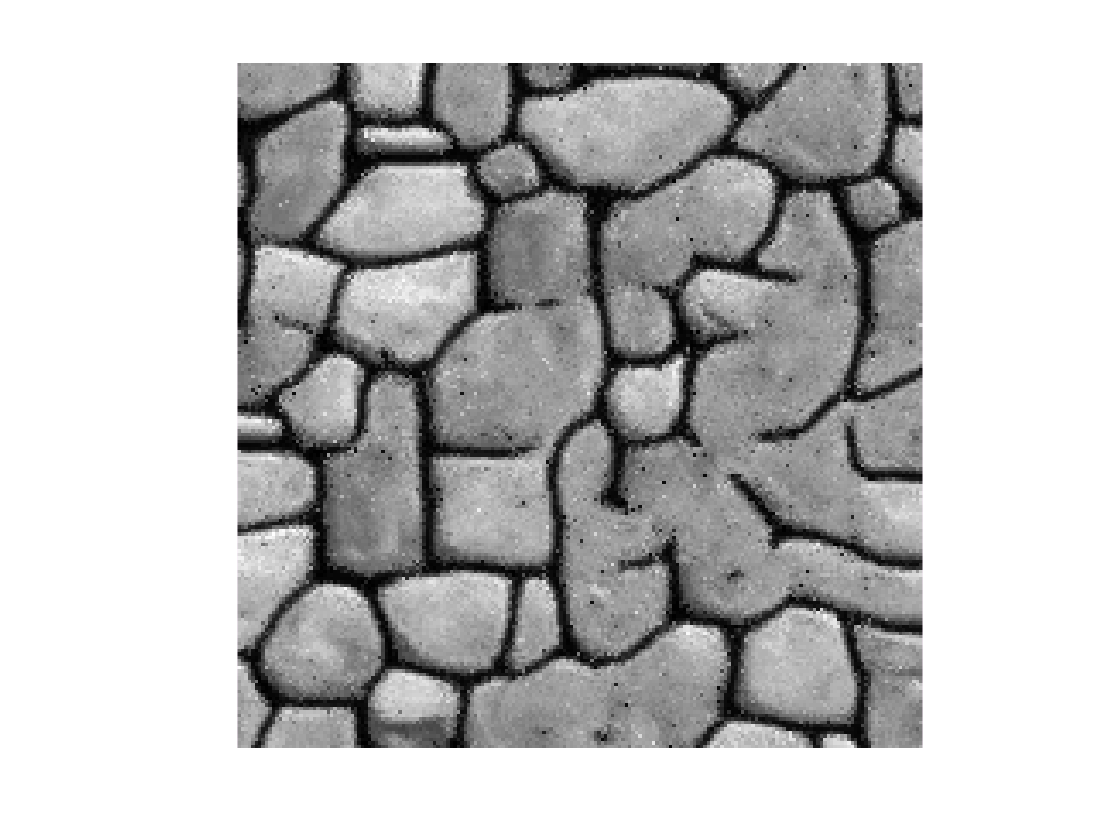

imshow(data)